# Ćwiczenia Audytoryjne 3 - 30.03.2023

## Zadanie 4.

2 osoby umówiły się na piwo. Przyjdą między 16:00 - a 17:00 i posziedzą 15 min. Jeśli się nie spotkają po tym czasie pojda sobie w swoje strony. Jakie jest prawdopodobieństwo że dojdzie do spotkania ?

p = 16.0:0.25:17.0; % Godzina przyjscia pierwszej osoby
d = 16.0:0.25:17.0; % Godzina przyjscia drugiej osoby

p - czas przyjścia I osoby.

d - czas przyjścia II osoby.

Ograniczenie od góry


$$u(p) = \begin{cases}
    p + \frac{1}{4} , & \text{ p \in [16 , 16\frac{3}{4} ] }..\\
    17, & \text{ p \in (16\frac{3}{4} , 17 ] }.
  \end{cases}$$


Ograniczenie od dołu


$$l(p) = \begin{cases}
    16 , & \text{ p \in [16 , 16\frac{1}{4} ] }..\\
    p - \frac{1}{4}, & \text{ p \in (16\frac{1}{4} , 17 ] }.
  \end{cases}$$


x = linspace(16,17)

x =    16.0000   16.0101   16.0202   16.0303   16.0404   16.0505   16.0606   16.0707   16.0808   16.0909   16.1010   16.1111   16.1212   16.1313   16.1414   16.1515   16.1616   16.1717   16.1818   16.1919   16.2020   16.2121   16.2222   16.2323   16.2424   16.2525   16.2626   16.2727   16.2828   16.2929   16.3030   16.3131   16.3232   16.3333   16.3434   16.3535   16.3636   16.3737   16.3838   16.3939   16.4040   16.4141   16.4242   16.4343   16.4444   16.4545   16.4646   16.4747   16.4848   16.4949


YL = yl(x)

YL =    16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0000   16.0025   16.0126   16.0227   16.0328   16.0429   16.0530   16.0631   16.0732   16.0833   16.0934   16.1035   16.1136   16.1237   16.1338   16.1439   16.1540   16.1641   16.1742   16.1843   16.1944   16.2045   16.2146   16.2247   16.2348   16.2449


YU = yu(x)

YU =    16.2500   16.2601   16.2702   16.2803   16.2904   16.3005   16.3106   16.3207   16.3308   16.3409   16.3510   16.3611   16.3712   16.3813   16.3914   16.4015   16.4116   16.4217   16.4318   16.4419   16.4520   16.4621   16.4722   16.4823   16.4924   16.5025   16.5126   16.5227   16.5328   16.5429   16.5530   16.5631   16.5732   16.5833   16.5934   16.6035   16.6136   16.6237   16.6338   16.6439   16.6540   16.6641   16.6742   16.6843   16.6944   16.7045   16.7146   16.7247   16.7348   16.7449


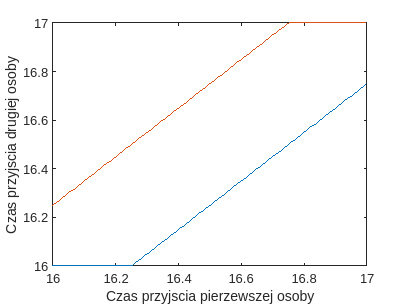


figure
plot(x,YL, x, YU)

xlabel("Czas przyjscia pierzewszej osoby")
ylabel("Czas przyjscia drugiej osoby")

Zatem wynik to pole obszaru ograniczonego dwoma funkcjami.


$$P\left ( \ l(p) \le d \le u(p) \ \right) = \int_{16}^{17} ( u(p) - l(p) ) \,dx \\
P( \ l(p) \le d \le u(p) \ ) = 1 - 2 * \left( \ \frac{3}{4} * \frac{3}{4} * \frac{1}{2} \ \right ) = \frac{7}{16}$$


function output = yu(x)
output = x + 1./4;
output(x > 16.75) = 17;
end

function output = yl(x)
output = x - 1./4;
output(x < 16.25) = 16;
end